## Cargar los valores reales del conjunto de datos

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["PCG_val", "PCG_res"];
opts.VariableTypes = ["string", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "PCG_val", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "PCG_val", "EmptyFieldRule", "auto");

% Import the data
REFERENCE = readtable("G:\Escuela Politécnica del Ejército\SeñalesCorazón\GUI\validation\REFERENCE.csv", opts)

REFERENCE = 301×2 table
    PCG_val    PCG_res
    _______    _______

    "a0001"       1   
    "a0002"       1   
    "a0003"       1   
    "a0004"       1   
    "a0005"       1   
    "a0006"       1   
    "a0007"      -1   
    "a0008"       1   
    "a0009"      -1   
    "a0010"       1   
    "a0011"      -1   
    "a0012"      -1   
    "a0013"       1   
    "a0014"       1   
    "a0015"       1   
    "a0016"      -1   



clear opts

## Cargar complementos necesarios

Springer_B_matrix = load('Springer_B_matrix.mat').Springer_B_matrix;
Springer_pi_vector = load('Springer_pi_vector.mat').Springer_pi_vector;
Springer_total_obs_distribution = load('Springer_total_obs_distribution.mat').Springer_total_obs_distribution;
springer_options = default_Springer_HSMM_options;
parms = load('parms_cnn.mat').parms;

% 3-5 min to run (aprox.)
% datastore
fds = fileDatastore("validation\*.wav", "ReadFcn", @audioread, "UniformRead", true);
full_paths = fds.Files;

for i = 1:length(full_paths)
    full_path = full_paths{i};
    splited_path = split(full_path, '\');
    signal_name = splited_path{end}(1:end-4)
    
    [data, fs] = audioread(full_path);
    if length(data) > 60*fs
        data = data(1:60*fs);
    end

    % resample to 1000 Hz
    PCG_resampled = resample(data, springer_options.audio_Fs, ...
        fs); % resample to springer_options.audio_Fs (1000 Hz)
    % filter the signal between 25 to 400 Hz
    base_signal = PCG_resampled * 0.5 / rms(PCG_resampled);
    PCG_resampled = butterworth_low_pass_filter(PCG_resampled, ...
        2, 400, springer_options.audio_Fs, false);
    PCG_resampled = butterworth_high_pass_filter(PCG_resampled, ...
        2, 25, springer_options.audio_Fs, false);
    % remove spikes
    PCG_resampled = schmidt_spike_removal(PCG_resampled, ...
        springer_options.audio_Fs);
    
    % wavelet
    data_w = PCG_resampled * 0.5 / rms(PCG_resampled);
    [c, l] = wavedec(data_w, 3, 'db1');
    b = wthresh(c, 's', 0.1);
    filtered_data = waverec(b, l, 'db1');
    filtered_data = filtered_data * 0.5 / rms(filtered_data);
    
    [assigned_states,t1,norm_sig] = runSpringerSegmentationAlgorithm(PCG_resampled,... 
                                springer_options.audio_Fs,... 
                                Springer_B_matrix, Springer_pi_vector,...
                                Springer_total_obs_distribution, false);
                            
    % get states
    idx_states = get_states(assigned_states);
                
    %% CNN
    parms.maxpooling = 2;
    
    N=60; sr = 1000; 
    Wn = 45*2/sr; 
    b1 = fir1(N, Wn, 'low', hamming(N+1));
    Wn = [45*2/sr, 80*2/sr];
    b2 = fir1(N, Wn, hamming(N+1));
    Wn = [80*2/sr, 200*2/sr];
    b3 = fir1(N, Wn, hamming(N+1));
    Wn = 200*2/sr;
    b4 = fir1(N, Wn, 'high', hamming(N+1));
    
    % filter signal in 4 different frequency bands,
    % [0,45],[45-80],[80-200],[200-400]
    clear PCG
    PCG(:,1) = filtfilt(b1, 1, PCG_resampled);
    PCG(:,2) = filtfilt(b2, 1, PCG_resampled);
    PCG(:,3) = filtfilt(b3, 1, PCG_resampled);
    PCG(:,4) = filtfilt(b4, 1, PCG_resampled);
    
    nfb = 4;
    nsamp = 2500;
    ncc = size(idx_states, 1)-1;
    X = nan(ncc, nsamp, nfb);
    for row=1:ncc
        for fb=1:nfb
            tmp = PCG(idx_states(row,1):idx_states(row+1,1),fb);
            N = nsamp-length(tmp);
            % append zeros at the end of cardiac cycle
            X(row,:,fb) = [tmp; zeros(N,1)];
        end
    end
    
    % run cnn feedforward
    res = nan(size(X,1), 2);
    for sample = 1:size(X,1)  
        s = squeeze(X(sample,:,:));
        res(sample,:) = feed_forward_cnn(s,parms);
    end
    prb_cnn = mean(res(:,2));
    
    if (prb_cnn > 0.4)
        classifyResult = 1;
        %app.text_result = 'anómalo';
    else
        classifyResult = -1;
        %app.text_result = 'normal';
    end
    % classifyResult: integer value where
    %                     1 = abnormal recording
    %                    -1 = normal recording
    %                     0 = unsure (too noisy)
    classifyResult
    newPCG(i).PCG_val = signal_name;
    newPCG(i).PCG_res = classifyResult;

end

signal_name = 'a0001'

classifyResult = 1

signal_name = 'a0002'

classifyResult = 1

signal_name = 'a0003'

classifyResult = 1

signal_name = 'a0004'

classifyResult = 1

signal_name = 'a0005'

classifyResult = 1

signal_name = 'a0006'

classifyResult = 1

signal_name = 'a0007'

classifyResult = -1

signal_name = 'a0008'

classifyResult = 1

signal_name = 'a0009'

classifyResult = 1

signal_name = 'a0010'

classifyResult = 1

signal_name = 'a0011'

classifyResult = -1

signal_name = 'a0012'

classifyResult = -1

signal_name = 'a0013'

classifyResult = 1

signal_name = 'a0014'

classifyResult = 1

signal_name = 'a0015'

classifyResult = 1

signal_name = 'a0016'

classifyResult = -1

signal_name = 'a0017'

classifyResult = 1

signal_name = 'a0018'

classifyResult = 1

signal_name = 'a0019'

classifyResult = -1

signal_name = 'a0020'

classifyResult = 1

signal_name = 'a0021'

classifyResult = 1

signal_name = 'a0022'

classifyResult = 1

signal_name = 'a0023'

classifyResult = 1

signal_name = 'a0024'

classifyResult = 1

signal_name = 'a0025'

classifyResult = -1

signal_name = 'a0026'

classifyResult = 1

signal_name = 'a0027'

classifyResult = -1

signal_name = 'a0028'

classifyResult = 1

signal_name = 'a0029'

classifyResult = 1

signal_name = 'a0030'

classifyResult = 1

signal_name = 'a0031'

classifyResult = 1

signal_name = 'a0032'

classifyResult = 1

signal_name = 'a0033'

classifyResult = 1

signal_name = 'a0034'

classifyResult = 1

signal_name = 'a0035'

classifyResult = 1

signal_name = 'a0036'

classifyResult = 1

signal_name = 'a0037'

classifyResult = 1

signal_name = 'a0038'

classifyResult = 1

signal_name = 'a0039'

classifyResult = 1

signal_name = 'a0040'

classifyResult = 1

signal_name = 'a0041'

classifyResult = 1

signal_name = 'a0042'

classifyResult = 1

signal_name = 'a0043'

classifyResult = -1

signal_name = 'a0044'

classifyResult = 1

signal_name = 'a0045'

classifyResult = 1

signal_name = 'a0046'

classifyResult = 1

signal_name = 'a0047'

classifyResult = -1

signal_name = 'a0048'

classifyResult = 1

signal_name = 'a0049'

classifyResult = -1

signal_name = 'a0050'

classifyResult = -1

signal_name = 'a0051'

classifyResult = 1

signal_name = 'a0052'

classifyResult = 1

signal_name = 'a0053'

classifyResult = 1

signal_name = 'a0054'

classifyResult = 1

signal_name = 'a0055'

classifyResult = -1

signal_name = 'a0056'

classifyResult = 1

signal_name = 'a0057'

classifyResult = -1

signal_name = 'a0068'

classifyResult = 1

signal_name = 'a0069'

classifyResult = -1

signal_name = 'a0070'

classifyResult = -1

signal_name = 'a0071'

classifyResult = -1

signal_name = 'a0080'

classifyResult = -1

signal_name = 'a0081'

classifyResult = -1

signal_name = 'a0085'

classifyResult = -1

signal_name = 'a0086'

classifyResult = 1

signal_name = 'a0088'

classifyResult = -1

signal_name = 'a0091'

classifyResult = -1

signal_name = 'a0093'

classifyResult = 1

signal_name = 'a0094'

classifyResult = -1

signal_name = 'a0102'

classifyResult = -1

signal_name = 'a0105'

classifyResult = -1

signal_name = 'a0106'

classifyResult = 1

signal_name = 'a0108'

classifyResult = 1

signal_name = 'a0109'

classifyResult = -1

signal_name = 'a0118'

classifyResult = -1

signal_name = 'a0125'

classifyResult = -1

signal_name = 'a0127'

classifyResult = -1

signal_name = 'a0129'

classifyResult = -1

signal_name = 'a0136'

classifyResult = -1

signal_name = 'a0139'

classifyResult = 1

signal_name = 'b0001'

classifyResult = 1

signal_name = 'b0002'

classifyResult = -1

signal_name = 'b0003'

classifyResult = -1

signal_name = 'b0004'

classifyResult = -1

signal_name = 'b0005'

classifyResult = -1

signal_name = 'b0006'

classifyResult = -1

signal_name = 'b0007'

classifyResult = 1

signal_name = 'b0008'

classifyResult = 1

signal_name = 'b0009'

classifyResult = -1

signal_name = 'b0010'

classifyResult = 1

signal_name = 'b0011'

classifyResult = -1

signal_name = 'b0012'

classifyResult = 1

signal_name = 'b0013'

classifyResult = 1

signal_name = 'b0014'

classifyResult = -1

signal_name = 'b0015'

classifyResult = -1

signal_name = 'b0016'

classifyResult = 1

signal_name = 'b0017'

classifyResult = -1

signal_name = 'b0018'

classifyResult = 1

signal_name = 'b0019'

classifyResult = 1

signal_name = 'b0020'

classifyResult = -1

signal_name = 'b0021'

classifyResult = -1

signal_name = 'b0022'

classifyResult = 1

signal_name = 'b0023'

classifyResult = 1

signal_name = 'b0024'

classifyResult = 1

signal_name = 'b0025'

classifyResult = -1

signal_name = 'b0026'

classifyResult = -1

signal_name = 'b0027'

classifyResult = -1

signal_name = 'b0028'

classifyResult = -1

signal_name = 'b0029'

classifyResult = -1

signal_name = 'b0030'

classifyResult = 1

signal_name = 'b0031'

classifyResult = 1

signal_name = 'b0032'

classifyResult = 1

signal_name = 'b0033'

classifyResult = 1

signal_name = 'b0034'

classifyResult = 1

signal_name = 'b0035'

classifyResult = 1

signal_name = 'b0036'

classifyResult = 1

signal_name = 'b0037'

classifyResult = 1

signal_name = 'b0038'

classifyResult = -1

signal_name = 'b0039'

classifyResult = -1

signal_name = 'b0040'

classifyResult = 1

signal_name = 'b0041'

classifyResult = 1

signal_name = 'b0042'

classifyResult = 1

signal_name = 'b0043'

classifyResult = -1

signal_name = 'b0044'

classifyResult = -1

signal_name = 'b0045'

classifyResult = 1

signal_name = 'b0046'

classifyResult = 1

signal_name = 'b0047'

classifyResult = -1

signal_name = 'b0048'

classifyResult = 1

signal_name = 'b0049'

classifyResult = -1

signal_name = 'b0050'

classifyResult = -1

signal_name = 'b0051'

classifyResult = 1

signal_name = 'b0052'

classifyResult = -1

signal_name = 'b0053'

classifyResult = 1

signal_name = 'b0054'

classifyResult = 1

signal_name = 'b0055'

classifyResult = -1

signal_name = 'b0056'

classifyResult = 1

signal_name = 'b0057'

classifyResult = 1

signal_name = 'b0058'

classifyResult = 1

signal_name = 'b0059'

classifyResult = 1

signal_name = 'b0060'

classifyResult = -1

signal_name = 'b0061'

classifyResult = -1

signal_name = 'b0062'

classifyResult = 1

signal_name = 'b0063'

classifyResult = -1

signal_name = 'b0064'

classifyResult = -1

signal_name = 'b0065'

classifyResult = 1

signal_name = 'b0066'

classifyResult = -1

signal_name = 'b0067'

classifyResult = 1

signal_name = 'b0068'

classifyResult = 1

signal_name = 'b0077'

classifyResult = 1

signal_name = 'b0081'

classifyResult = 1

signal_name = 'b0086'

classifyResult = 1

signal_name = 'b0096'

classifyResult = 1

signal_name = 'b0106'

classifyResult = 1

signal_name = 'b0117'

classifyResult = -1

signal_name = 'b0120'

classifyResult = 1

signal_name = 'b0130'

classifyResult = 1

signal_name = 'b0136'

classifyResult = 1

signal_name = 'b0137'

classifyResult = -1

signal_name = 'b0140'

classifyResult = 1

signal_name = 'b0148'

classifyResult = 1

signal_name = 'b0155'

classifyResult = 1

signal_name = 'b0159'

classifyResult = -1

signal_name = 'b0164'

classifyResult = 1

signal_name = 'b0171'

classifyResult = 1

signal_name = 'b0176'

classifyResult = 1

signal_name = 'b0190'

classifyResult = 1

signal_name = 'b0197'

classifyResult = 1

signal_name = 'b0208'

classifyResult = 1

signal_name = 'b0221'

classifyResult = 1

signal_name = 'b0224'

classifyResult = -1

signal_name = 'b0232'

classifyResult = 1

signal_name = 'b0233'

classifyResult = 1

signal_name = 'b0235'

classifyResult = 1

signal_name = 'b0238'

classifyResult = 1

signal_name = 'b0239'

classifyResult = 1

signal_name = 'b0242'

classifyResult = -1

signal_name = 'b0243'

classifyResult = 1

signal_name = 'b0248'

classifyResult = 1

signal_name = 'c0001'

classifyResult = -1

signal_name = 'c0002'

classifyResult = 1

signal_name = 'c0003'

classifyResult = -1

signal_name = 'c0004'

classifyResult = 1

signal_name = 'c0006'

classifyResult = -1

signal_name = 'c0007'

classifyResult = -1

signal_name = 'c0031'

classifyResult = 1

signal_name = 'd0001'

classifyResult = 1

signal_name = 'd0002'

classifyResult = -1

signal_name = 'd0003'

classifyResult = 1

signal_name = 'd0004'

classifyResult = -1

signal_name = 'd0005'

classifyResult = -1

signal_name = 'd0006'

classifyResult = 1

signal_name = 'd0007'

classifyResult = 1

signal_name = 'd0008'

classifyResult = 1

signal_name = 'd0009'

classifyResult = 1

signal_name = 'd0013'

classifyResult = 1

signal_name = 'e00001'

classifyResult = -1

signal_name = 'e00002'

classifyResult = -1

signal_name = 'e00003'

classifyResult = -1

signal_name = 'e00004'

classifyResult = -1

signal_name = 'e00005'

classifyResult = -1

signal_name = 'e00006'

classifyResult = -1

signal_name = 'e00007'

classifyResult = -1

signal_name = 'e00008'

classifyResult = -1

signal_name = 'e00009'

classifyResult = -1

signal_name = 'e00010'

classifyResult = -1

signal_name = 'e00011'

classifyResult = -1

signal_name = 'e00012'

classifyResult = -1

signal_name = 'e00013'

classifyResult = -1

signal_name = 'e00014'

classifyResult = -1

signal_name = 'e00015'

classifyResult = -1

signal_name = 'e00016'

classifyResult = -1

signal_name = 'e00017'

classifyResult = -1

signal_name = 'e00018'

classifyResult = -1

signal_name = 'e00019'

classifyResult = -1

signal_name = 'e00020'

classifyResult = 1

signal_name = 'e00021'

classifyResult = -1

signal_name = 'e00022'

classifyResult = -1

signal_name = 'e00023'

classifyResult = -1

signal_name = 'e00024'

classifyResult = -1

signal_name = 'e00025'

classifyResult = -1

signal_name = 'e00026'

classifyResult = -1

signal_name = 'e00027'

classifyResult = -1

signal_name = 'e00028'

classifyResult = -1

signal_name = 'e00029'

classifyResult = -1

signal_name = 'e00030'

classifyResult = -1

signal_name = 'e00031'

classifyResult = -1

signal_name = 'e00032'

classifyResult = -1

signal_name = 'e00033'

classifyResult = -1

signal_name = 'e00034'

classifyResult = -1

signal_name = 'e00035'

classifyResult = -1

signal_name = 'e00036'

classifyResult = -1

signal_name = 'e00037'

classifyResult = -1

signal_name = 'e00038'

classifyResult = -1

signal_name = 'e00039'

classifyResult = -1

signal_name = 'e00040'

classifyResult = -1

signal_name = 'e00041'

classifyResult = -1

signal_name = 'e00042'

classifyResult = -1

signal_name = 'e00043'

classifyResult = -1

signal_name = 'e00044'

classifyResult = -1

signal_name = 'e00045'

classifyResult = -1

signal_name = 'e00046'

classifyResult = -1

signal_name = 'e00047'

classifyResult = -1

signal_name = 'e00048'

classifyResult = 1

signal_name = 'e00049'

classifyResult = -1

signal_name = 'e00050'

classifyResult = -1

signal_name = 'e00051'

classifyResult = -1

signal_name = 'e00052'

classifyResult = -1

signal_name = 'e00053'

classifyResult = -1

signal_name = 'e00054'

classifyResult = -1

signal_name = 'e00055'

classifyResult = -1

signal_name = 'e00059'

classifyResult = 1

signal_name = 'e00071'

classifyResult = 1

signal_name = 'e00087'

classifyResult = 1

signal_name = 'e00097'

classifyResult = 1

signal_name = 'e00114'

classifyResult = 1

signal_name = 'e00120'

classifyResult = 1

signal_name = 'e00135'

classifyResult = 1

signal_name = 'e00140'

classifyResult = 1

signal_name = 'e00142'

classifyResult = 1

signal_name = 'e00152'

classifyResult = 1

signal_name = 'e00176'

classifyResult = 1

signal_name = 'e00191'

classifyResult = 1

signal_name = 'e00195'

classifyResult = 1

signal_name = 'e00216'

classifyResult = 1

signal_name = 'e00228'

classifyResult = 1

signal_name = 'e00266'

classifyResult = 1

signal_name = 'e00275'

classifyResult = 1

signal_name = 'e00295'

classifyResult = 1

signal_name = 'e00304'

classifyResult = 1

signal_name = 'e00305'

classifyResult = 1

signal_name = 'e00321'

classifyResult = 1

signal_name = 'e00328'

classifyResult = 1

signal_name = 'e00330'

classifyResult = 1

signal_name = 'e00336'

classifyResult = 1

signal_name = 'e00359'

classifyResult = 1

signal_name = 'e00373'

classifyResult = 1

signal_name = 'e00388'

classifyResult = 1

signal_name = 'e00435'

classifyResult = 1

signal_name = 'e00456'

classifyResult = 1

signal_name = 'e00457'

classifyResult = 1

signal_name = 'e00461'

classifyResult = 1

signal_name = 'e00475'

classifyResult = 1

signal_name = 'e00477'

classifyResult = 1

signal_name = 'e00523'

classifyResult = 1

signal_name = 'e00526'

classifyResult = 1

signal_name = 'e00528'

classifyResult = 1

signal_name = 'e00536'

classifyResult = 1

signal_name = 'e00537'

classifyResult = 1

signal_name = 'e00539'

classifyResult = 1

signal_name = 'e00551'

classifyResult = 1

signal_name = 'e00562'

classifyResult = 1

signal_name = 'e00591'

classifyResult = 1

signal_name = 'e00601'

classifyResult = 1

signal_name = 'e00603'

classifyResult = 1

signal_name = 'e00605'

classifyResult = 1

signal_name = 'e00619'

classifyResult = 1

signal_name = 'e00622'

classifyResult = 1

signal_name = 'e00627'

classifyResult = 1

signal_name = 'e00648'

classifyResult = 1

signal_name = 'e00657'

classifyResult = 1

signal_name = 'e00670'

classifyResult = 1

%struct2table(newPCG)

PREDICTED = struct2table(newPCG)

PREDICTED = 301×2 table
     PCG_val     PCG_res
    _________    _______

    {'a0001'}       1   
    {'a0002'}       1   
    {'a0003'}       1   
    {'a0004'}       1   
    {'a0005'}       1   
    {'a0006'}       1   
    {'a0007'}      -1   
    {'a0008'}       1   
    {'a0009'}       1   
    {'a0010'}       1   
    {'a0011'}      -1   
    {'a0012'}      -1   
    {'a0013'}       1   
    {'a0014'}       1   
    {'a0015'}       1   
    {'a0016'}      -1   


C = confusionmat(REFERENCE.PCG_res, PREDICTED.PCG_res)

C =    113    37
    13   138


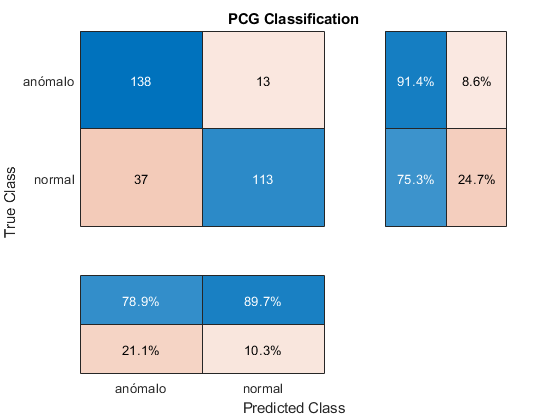

cm = confusionchart(C, ["normal", "anómalo"]);
cm.Title = 'PCG Classification';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

classperf((REFERENCE.PCG_res+1)/2, (PREDICTED.PCG_res+1)/2)

                        Label: ''
                  Description: ''
                  ClassLabels: [2×1 double]
                  GroundTruth: [301×1 double]
         NumberOfObservations: 301
               ControlClasses: 2
                TargetClasses: 1
            ValidationCounter: 1
           SampleDistribution: [301×1 double]
            ErrorDistribution: [301×1 double]
    SampleDistributionByClass: [2×1 double]
     ErrorDistributionByClass: [2×1 double]
               CountingMatrix: [3×2 double]
                  CorrectRate: 0.8339
                    ErrorRate: 0.1661
              LastCorrectRate: 0.8339
                LastErrorRate: 0.1661
             InconclusiveRate: 0
               ClassifiedRate: 1
                  Sensitivity: 0.7533
                  Specificity: 0.9139
      PositivePredictiveValue: 0.8968
      NegativePredictiveValue: 0.7886
           PositiveLikelihood: 8.7503
           NegativeLikelihood: 0.2699
                   Prevalence: 0.4983
